# Example 8.1: Matrix-based discrete Fourier transforms (DFTs).

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

The discrete Fourier transform (DFT) of Chapter 4 is an orthonormal transform that can alternately be written 


$$F(u,v) = \sum_{x=0}^{M-1} \sum_{y=0}^{N-1} f(x,y) \left[ \frac{1}{\sqrt{MN}} e^{-j2\pi(ux/N + vy/N)}\right]$$


and


$$f(x,y) = \sum_{u=0}^{M-1} \sum_{v=0}^{N-1} T(u,v) \left[ \frac{1}{\sqrt{MN}} e^{j2\pi(ux/M + uy/N}  \right] $$


where the $1/MN$ term in Eq. (4-2) has been split between the bracketed forward and inverse transformation kernels in Eqs. (8-10) and (8-11). For square images, $M=N$, $1/\sqrt{MN} = 1/N$, and the DFT expansion functions are


$$s(x,y,u,v) = r^{*}(x,y,u,v) = \frac{1}{N} e^{j2\pi(ux/N + vy/N)}$$
 

Because they are separable and symmetric, $s(x,y,u,v) = s(x,u) s(y,v)$and we can write 


$$s(x,u) = \frac{1}{\sqrt{N}} e^{j2\pi ux/N}$$



$$s(y,v) = \frac{1}{\sqrt{N}} e^{j2\pi vy/N}$$


For the case of $N=4$, substitution of Eq. (8-13) into Eq. (8-6) yields four basis vectors


$${\mathbf{s}}_0 =\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
1\\
1\\
1
\end{array}\right\rbrack$$
    
$${\mathbf{s}}_0 =\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
-j\\
1\\
j
\end{array}\right\rbrack$$
    
$${\mathbf{s}}_0 =\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
-1\\
1\\
-1
\end{array}\right\rbrack$$
    
$${\mathbf{s}}_0 =\frac{1}{2}\left\lbrack \begin{array}{c}
1\\
j\\
-1\\
-j
\end{array}\right\rbrack$$


and transformation matrix $\mathbf{A}$, in accordance with Eq. (8-9), becomes 

In MATLAB, a DFT transformation matrix can be computed using function `dftmtx`, whose general syntax is 

where integer `N` is the dimension of transformation matrix `A`, and `A` is complex and of class `double`. Function `dftmtx` returns a scaled version of the transformation matrix defined by Eq. (8-9); prior to its use with the transforms in Table 8.1, it must be multiplied by `1/sqrt(N)`. Thus, for example, `dftmtx` and the transform pair in row 2 and column 3 of Table 8.1 can be used to compute the forward and inverse DFTs of a $4 \times 4$ image as follows: 			

F = magic(4)					

F =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


A = (1/sqrt(4))*dftmtx(4)

A =    0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i
   0.5000 + 0.0000i   0.0000 - 0.5000i  -0.5000 + 0.0000i   0.0000 + 0.5000i
   0.5000 + 0.0000i  -0.5000 + 0.0000i   0.5000 + 0.0000i  -0.5000 + 0.0000i
   0.5000 + 0.0000i   0.0000 + 0.5000i  -0.5000 + 0.0000i   0.0000 - 0.5000i


T = A*F*transpose(A)

T =   34.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   5.0000 + 0.0000i   2.0000 + 2.0000i   0.0000 - 3.0000i
   0.0000 + 0.0000i   8.0000 + 8.0000i   0.0000 + 0.0000i   8.0000 - 8.0000i
   0.0000 + 0.0000i   0.0000 + 3.0000i   2.0000 - 2.0000i   5.0000 + 0.0000i


F2 = transpose(conj(A))*T*conj(A)

F2 =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


max(max(F - F2))

ans = 0

Note that the maximum difference between F and F2 is 0. The DFT, as expected, is reversible. 

Figure 8.1 compares two different ways of computing the DFT of a $512 \times 512$ monochrome image. Figure 8.1(a) is the same white rectangle on a black back- ground that was discussed in conjunction with MATLAB’s `fft2` function in Fig. 4.3 of Section 4.2. Its spectrum, computed using the `fft2` function, is shown in Fig. 8.1(b). These two figures were generated by the following commands: 	

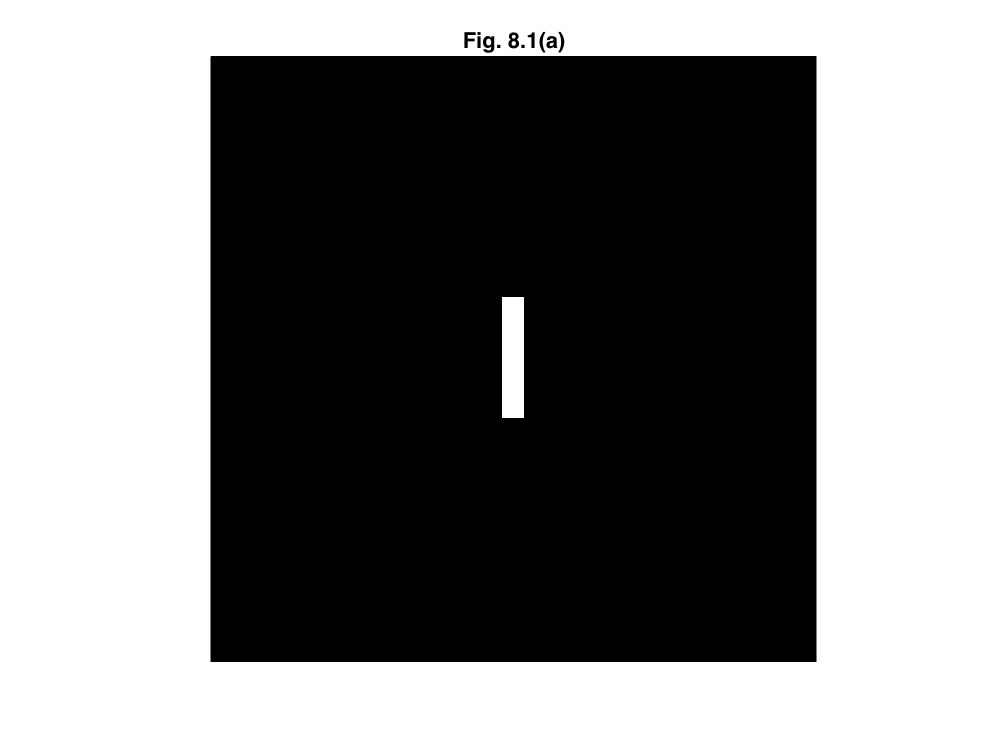

I = zeros(512,512);
I(205:306,247:265) = 1;
imshow(I); title('Fig. 8.1(a)')

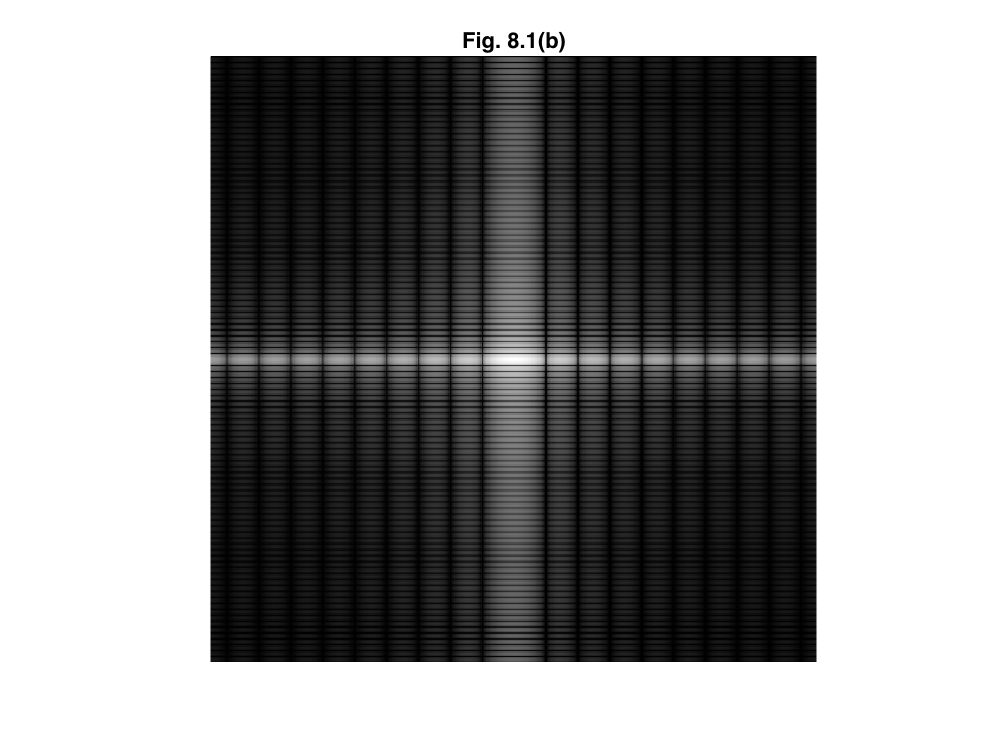

T = fft2(I);
figure; imshow(im2uint8(mat2gray(log(1 + abs(fftshift(T))))),[]); title('Fig. 8.1(b)')

Note that the `fft2`-based spectrum in Fig. 8.1(b) is both centered and log-scaled for ease of viewing and interpretation, as explained in Section 4.2. The spectrum in Fig. 8.1(c) is similarly scaled, but was computed using a $512 \times 512$ DFT transformation matrix and two matrix multiplications: 		

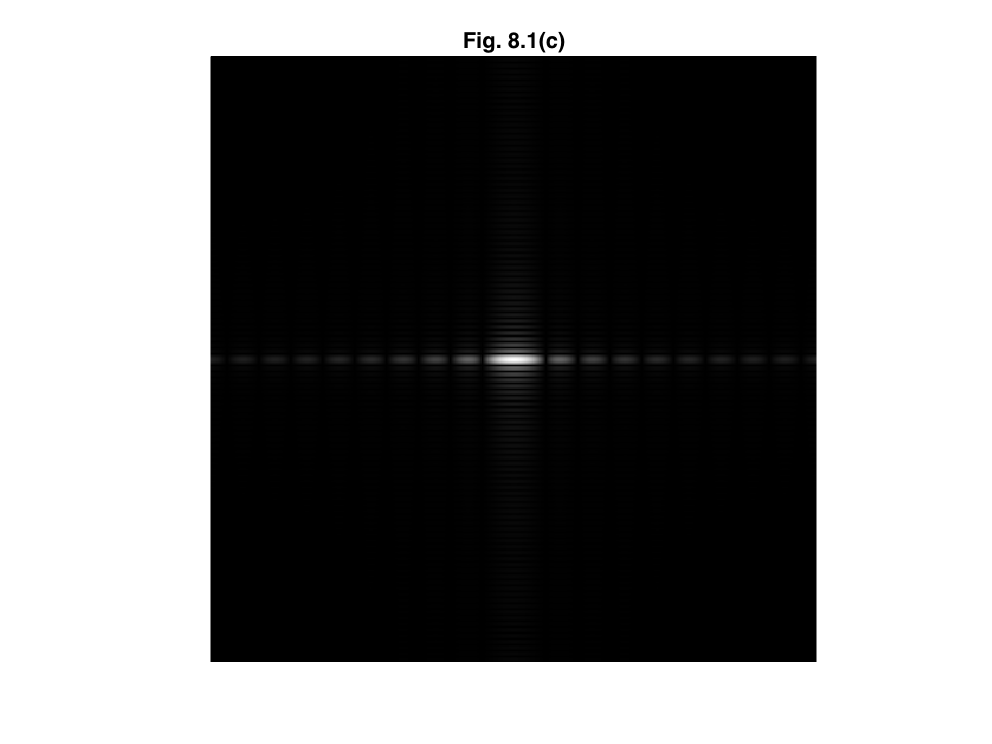

A = (1/sqrt(512))*dftmtx(512);
T = A*I*transpose(A);
figure; imshow(im2uint8(mat2gray(log(1 + abs(fftshift(T))))),[]); title('Fig. 8.1(c)')

The spectrum in Fig. 8.1(c) differs from that in (b), but if the matrix-based transform whose scaled spectrum is shown in (c) is scaled by 512 (to compensate for the added `1/sqrt(512)` scaling of A), the two become identical. Figure 8.1(d) shows the result of the additional scaling, which is accomplished with the following commands: 

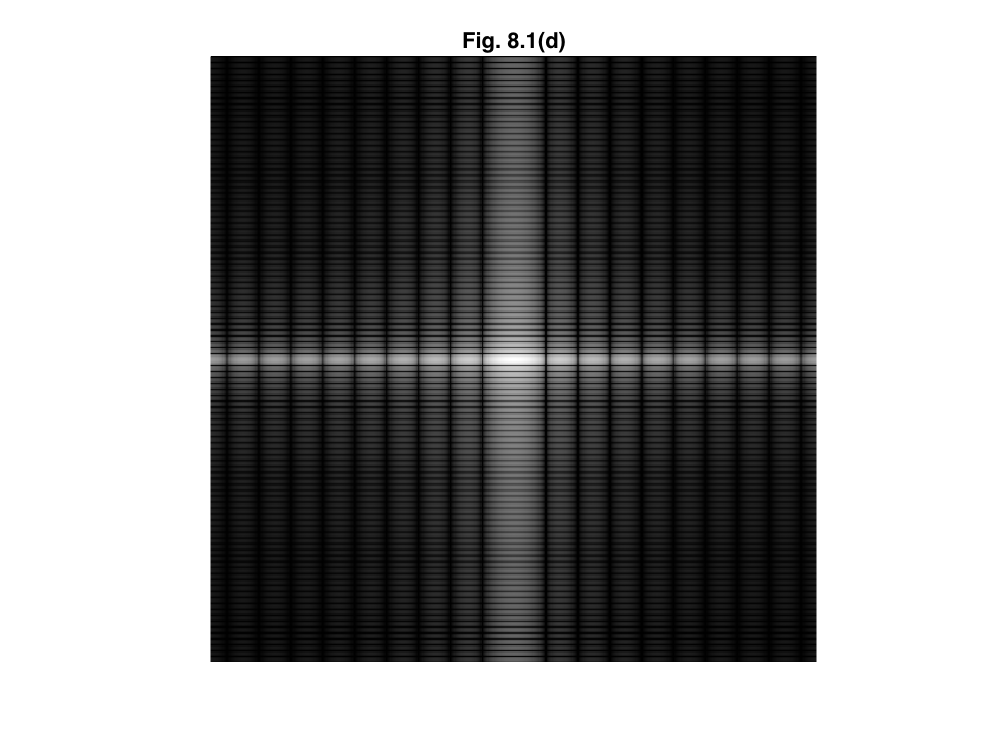

figure; imshow(im2uint8(mat2gray(log(1 + 512*abs(fftshift(T))))),[]); title('Fig. 8.1(d)')

The equivalency of the two transforms can be verified numerically using 

max(max(fft2(I) - 512*T))

ans = 2.2737e-12 + 1.7053e-13i

Note that the maximum difference between the two transforms is on the order of $10^{-10}$ due to rounding. Finally, we note that the execution times of the `fft2`-based and matrix-based transforms also differ: 				

timeit(@() fft2(I))

ans = 0.0010

timeit(@() (1/sqrt(512))*dftmtx(512))

ans = 7.8078e-04

timeit (@() A*I*transpose(A))

ans = 0.0197

The matrix-based transform is fast, requiring only 0.00056 + 0.019 = 0.0196 s, but MATLAB’s `fft2` function is almost 20 times faster, requiring a mere 0.0011 s. 